# Toy Experiments

MATLAB results don't give the linear operator on the regressand. So we have to do the estimation by hand.

## DGP

Adapted from Hastie & Tibshirani, p 12. $Y = \sin(\pi X)+\epsilon$

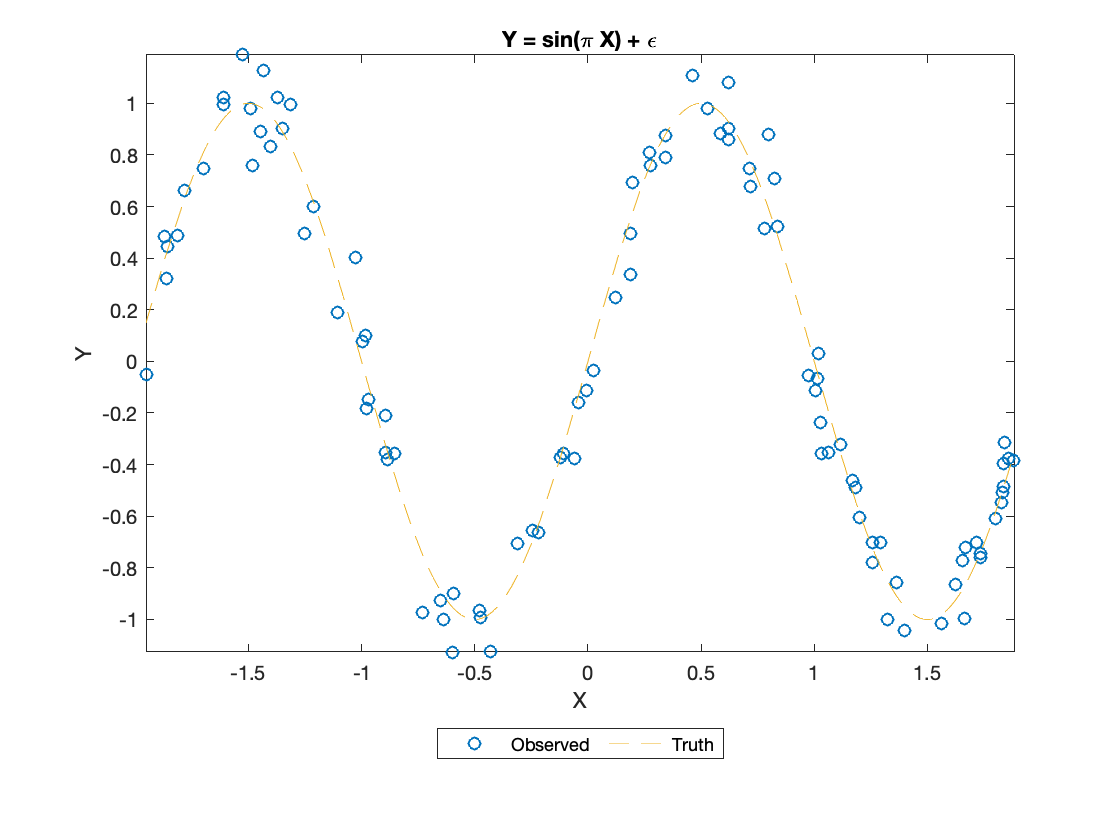

rng default; % For testing

n = 100;
k = 1;

%X = normrnd(0,1,n,k);
X = unifrnd(-2,2,n,k);
%X = binornd(1000,0.5,n,k)/250-2
X = sort(X);
epsilon = normrnd(0,1/9,n,k);
f = sin(pi*X);
plot_title = 'Y = sin(\pi X) + \epsilon';
Y = f+epsilon;
save('dgp.mat','X','Y');

y_limits = [min(Y) max(Y)];
plot(X,Y,'o');
hold on;
ax = gca;
ax.ColorOrderIndex = 3;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
title(plot_title);
legend('Observed', 'Truth','Location','bestoutside',...
    'Orientation','horizontal');
xlabel('X');
ylabel('Y');
hold off;

## Smoothness Measures

using setup from Hall & Racine 2015

"﻿Data pairs $(x_i, y_i)$ are assumed to be generated by the model, $y_i = g(x_i) + \epsilon_i$ where $x_1, ... , x_n$ are independent and identically distributed as x, with density $f(x)$ supported on a compact interval $\textit{I}$, and the experimental errors $\epsilon_i$ are independent and identically distributed with zero mean, independent too of the $x_i$s. The case where $\epsilon_i = \sigma(x)\epsilon_i'$ for a bounded function $\sigma$ and independent variables $\epsilon_i'$ with zero mean, independent of the $x_i$s, can be treated similarly."

MSE: $\int_\textit{I} (\hat{g}_\lambda(x)-g(x))^2f(x)dx$ approximated by ﻿$CV(\lambda) = \frac{1}{n} \sum\limits_{i=1}^n(y_i-\hat{g}_\lambda^{-i}(x_i))^2$ 

with $\hat{g}_\lambda(x_i) = S_i(\lambda)y$ where S_i is the i'th row of S


$$\hat{g}_\lambda^{-i}(x_i) = \sum\limits_{j=1, j \ne i}^n \frac{S_{ij}(\lambda)}{1-S_{ii}(\lambda)}y_j $$



$$y_i-\hat{g}_\lambda^{-i}(x_i) = \frac{y_i - S_{ii}(\lambda)y_i - \sum\limits_{j=1, j \ne i}^n S_{ij}(\lambda)y_j}{1-S_{ii}(\lambda)} = \frac{y_i-\hat{g}_\lambda(x_i)}{1-S_{ii}(\lambda)}$$



$$CV(\lambda) = \frac{1}{n} \sum\limits_{i=1}^n \Big(\frac{y_i-\hat{g}_\lambda(x_i)}{1-S_{ii}(\lambda)} \Big)^2$$



$$GCV(\lambda) = \frac{1}{n}\sum\limits_{i=1}^n \Bigg( \Bigg)$$


E(Y|X) = f(X), f arbitrary, unspecified

S as estimate of f, $S := \hat{f}(\lambda, X)$

$s(x_0) = \sum\limits_{j=1}^{n}S_{0j}(\lambda)y_j$ (linear in Y)

image of Y

do nothing as benchmark

A(Y) linear (AY is linear by definition)

references in mccloud and permutter

linear in Y

varNames ={'df_Var','df_Px','df_Fit', 'sum_SVD', 'sum_eig'};
rowNames = {'linear','affine','glPoly','NW','LL','regSpline',...
    'smoothSpline','interpSpline'};
s_rows = size(rowNames,2);
s_cols = size(varNames,2);
smoothness = table('Size',[s_rows s_cols],'VariableTypes',...
    [repmat("double",1,s_cols)],'VariableNames',varNames,...
    'RowNames',rowNames);

## OLS

### Linear


$$m = X(X'X)^{-1}X'Y$$


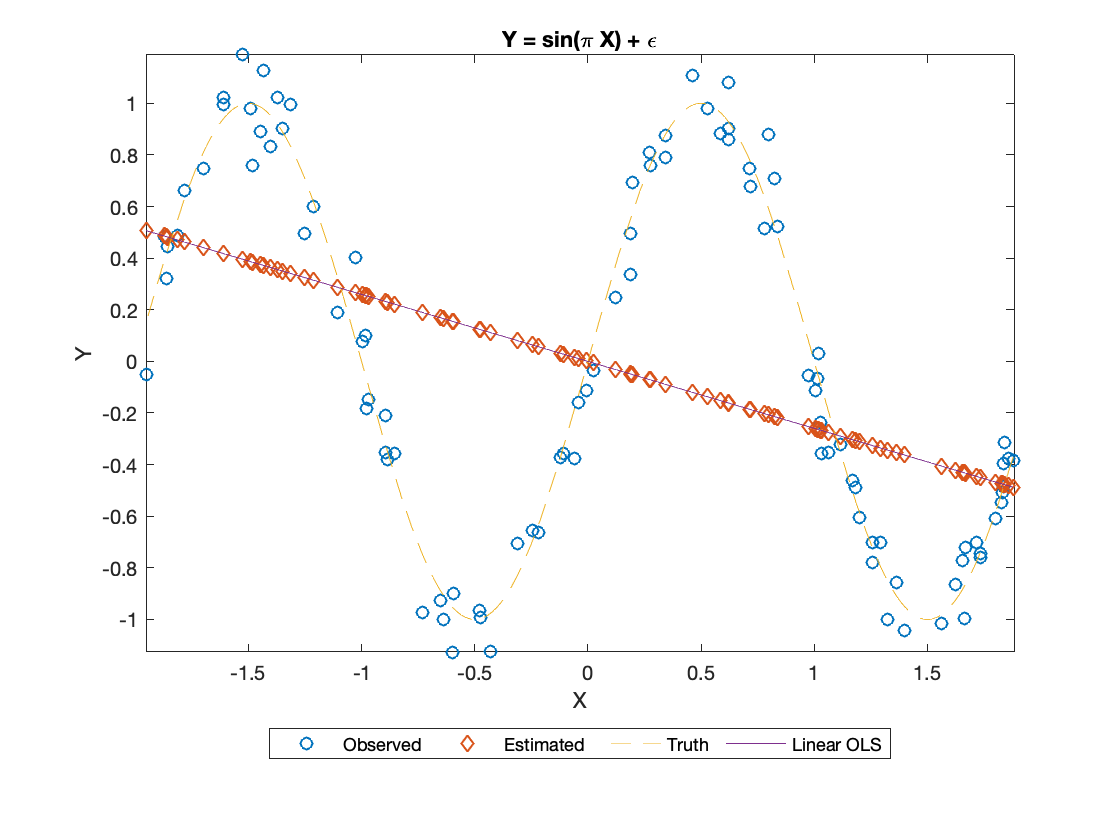

[n k] = size(X);

[U,S,V] = svd(X);
lo = X*(X'*X)^-1*X';
Y_lo = lo*Y;
beta_lo = (X'*X)^-1*X'*Y;

xx = X(1):0.01:X(n);
yy = beta_lo*xx;

y_limits = [min(min(Y),min(Y_lo)) max(max(Y),max(Y_lo))];
plot(X,Y,'o',X,Y_lo,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated','Truth','Linear OLS',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,lo,rowNames(1));

### Affine


$$m = [\mathbf{1_n} \enspace X]([\mathbf{1_n} \enspace X]'[\mathbf{1_n} \enspace X])^{-1}[\mathbf{1_n} \enspace X]'Y$$


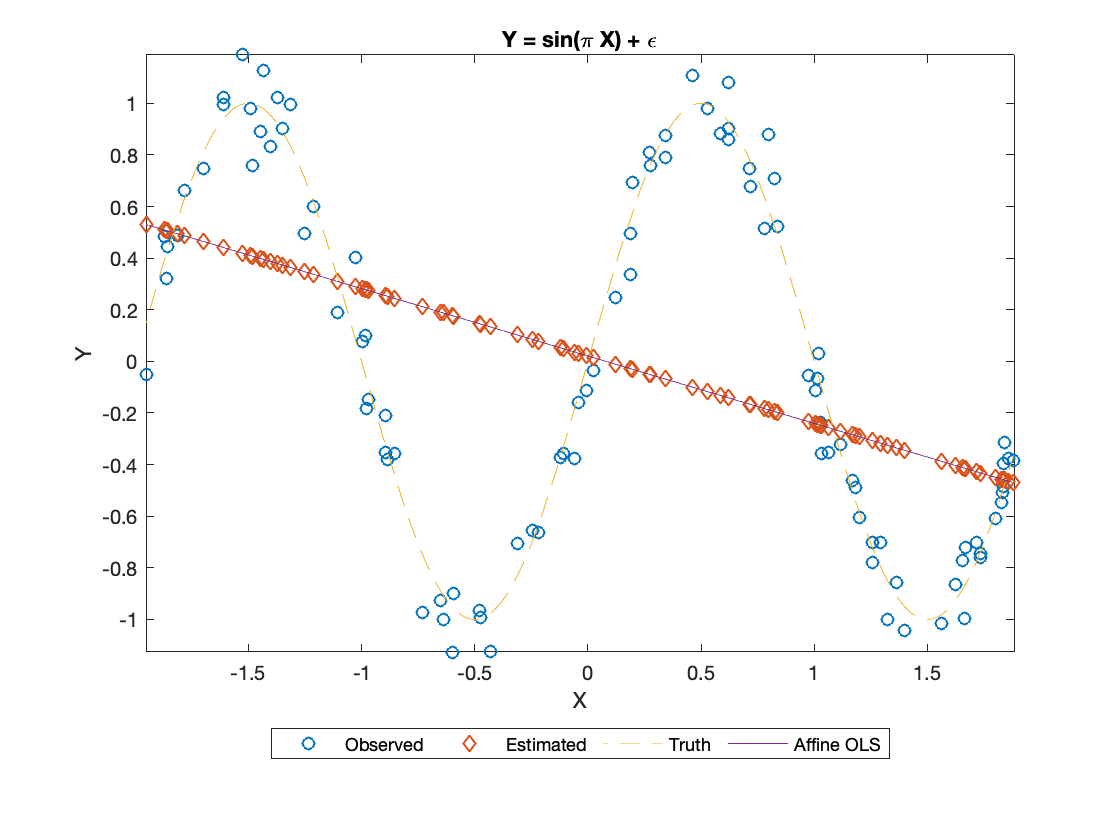

[n k] = size(X);
affineX = [ones(n,1) X];
ao = affineX*(affineX'*affineX)^-1*affineX';
Y_ao = ao*Y;
beta_ao = (affineX'*affineX)^-1*affineX'*Y;

xx = X(1):0.01:X(end);
yy = beta_ao(2)*xx+beta_ao(1);

y_limits = [min(min(Y),min(Y_ao)) max(max(Y),max(Y_ao))];
plot(X,Y,'o',X,Y_ao,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated','Truth','Affine OLS',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,ao,rowNames(2));

### Global Polynomial


$$m = [\mathbf{1_n} \enspace X \enspace X^2 ... X^p] ([\mathbf{1_n} \enspace X \enspace X^2 ... X^p]' [\mathbf{1_n} \enspace X \enspace X^2 ... X^p])^{-1}[[\mathbf{1_n} \enspace X \enspace X^2 ... X^p]]'Y$$


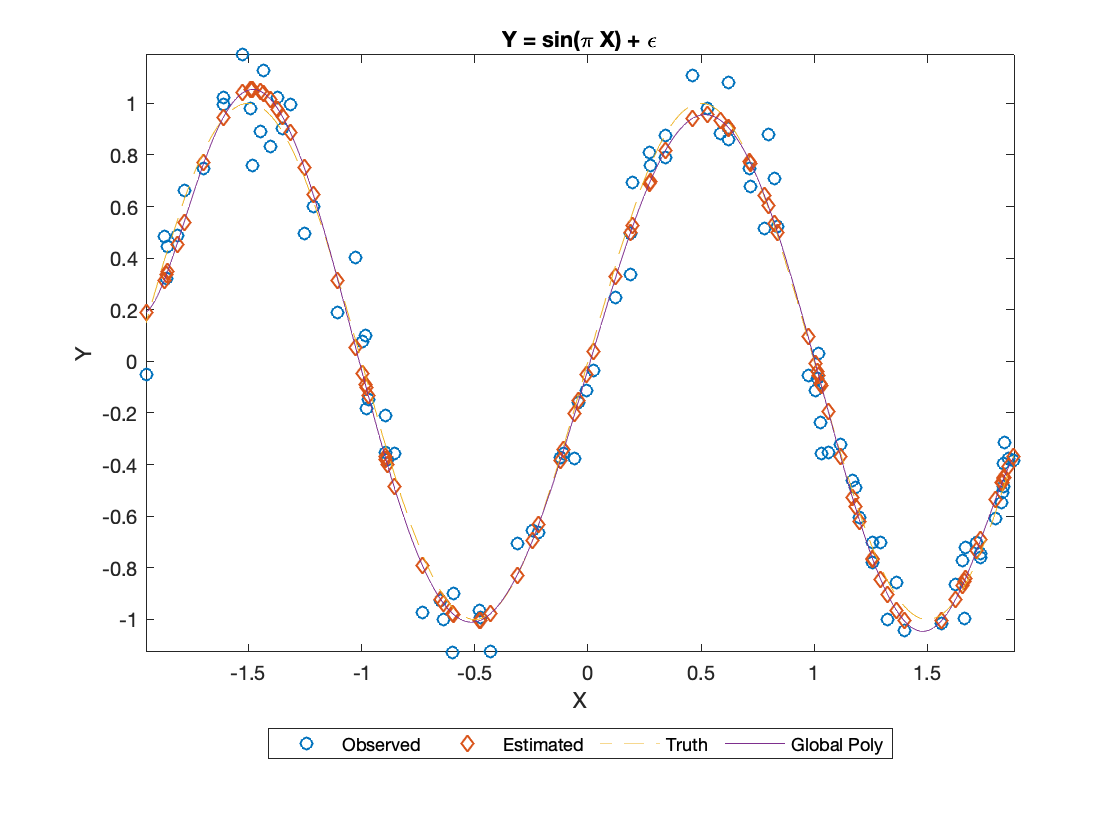

[n k] = size(X);
p = 7;
polyX = X.^(p:-1:0);
glP = polyX*(polyX'*polyX)^-1*polyX';
Y_glP = glP*Y;
beta_glP = (polyX'*polyX)^-1*polyX'*Y;

xx = X(1):0.01:X(end);
yy = (xx)'.^(p:-1:0)*beta_glP;

y_limits = [min(min(Y),min(Y_glP)) max(max(Y),max(Y_glP))];
plot(X,Y,'o',X,Y_glP,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated','Truth','Global Poly',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,glP,rowNames(3));

## Kernel-Based Estimators

Bandwidth choice

h=1;

### Nadaraya-Watson


$$\hat{m}(x_0) = \frac{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)y_l}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)}$$
 

$\hat{Y}_{NW} = KY$, with elements $k_{i,j} = \frac{k\Big(\frac{x_j-x_i}{h}\Big)}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_i}{h}\Big)}$ 

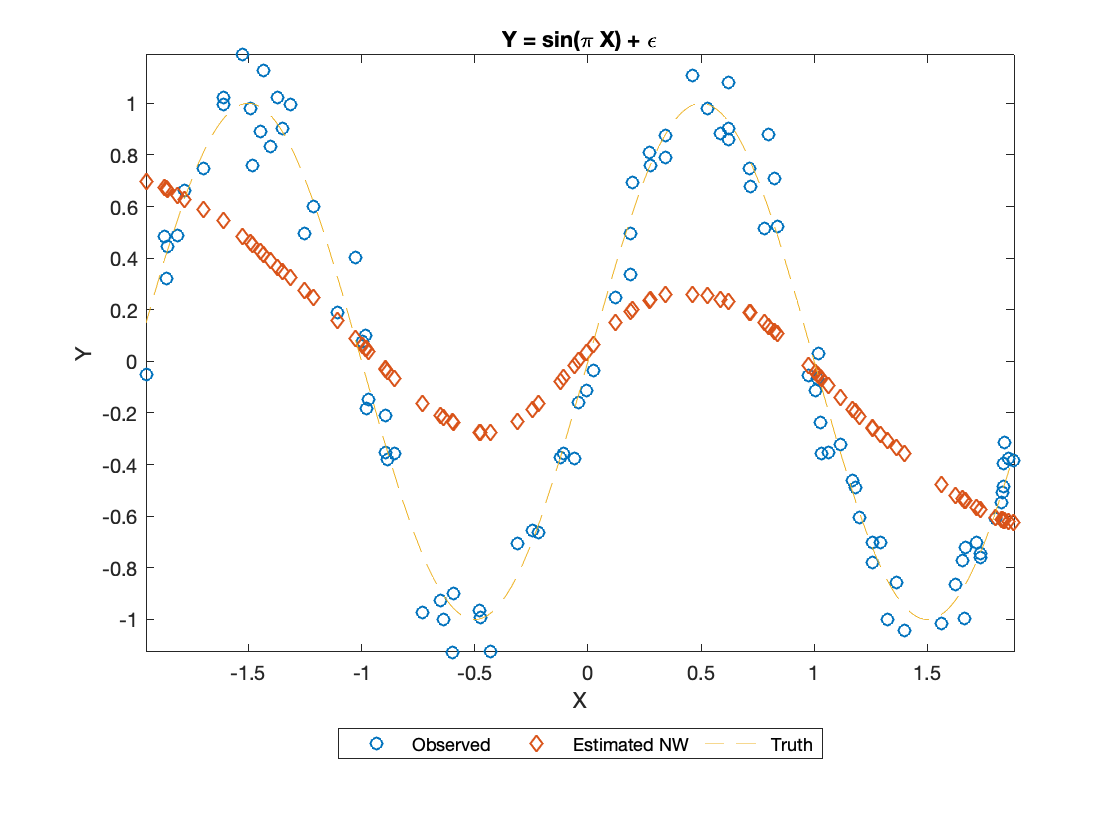

[n, k] = size(X);
% diff_ij = (x_j-x_i)/h
diff = (repmat(X',n,k)-repmat(X,k,n))/h;
%Epanechnikov kernel
numerator = 3/4*(ones(n*k)-diff.^2).*(abs(diff)<=1);
denominator = repmat(sum(numerator,2),k,n);
K = numerator./denominator;

Y_NW = K*Y;

y_limits = [min(min(Y),min(Y_NW)) max(max(Y),max(Y_NW))];
plot(X,Y,'o',X,Y_NW,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated NW','Truth',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,K,rowNames(4));

### Local Linear

$\tilde{m}(x_0) = [\mathbf{1_n} \enspace X_0]\big([\mathbf{1_n} \enspace X_0]'W_0[\mathbf{1_n} \enspace X_0]\big)^{-1}[\mathbf{1_n} \enspace X_0]'W_0Y$, where $X_0 = [X-x_0\mathbf{1_n} ]$ and $W_0 = diag[k\Big(\frac{x_1-x_0}{h}\Big), ... ,k\Big(\frac{x_n-x_0}{h}\Big)]$ 

$\hat{Y}_{LL} = LY$, with row L_i given as the i'th row of $[\mathbf{1_n} \enspace X_i]\big([\mathbf{1_n} \enspace X_i]'W_i[\mathbf{1_n} \enspace X_i]\big)^{-1}[\mathbf{1_n} \enspace X_i]'W_i$

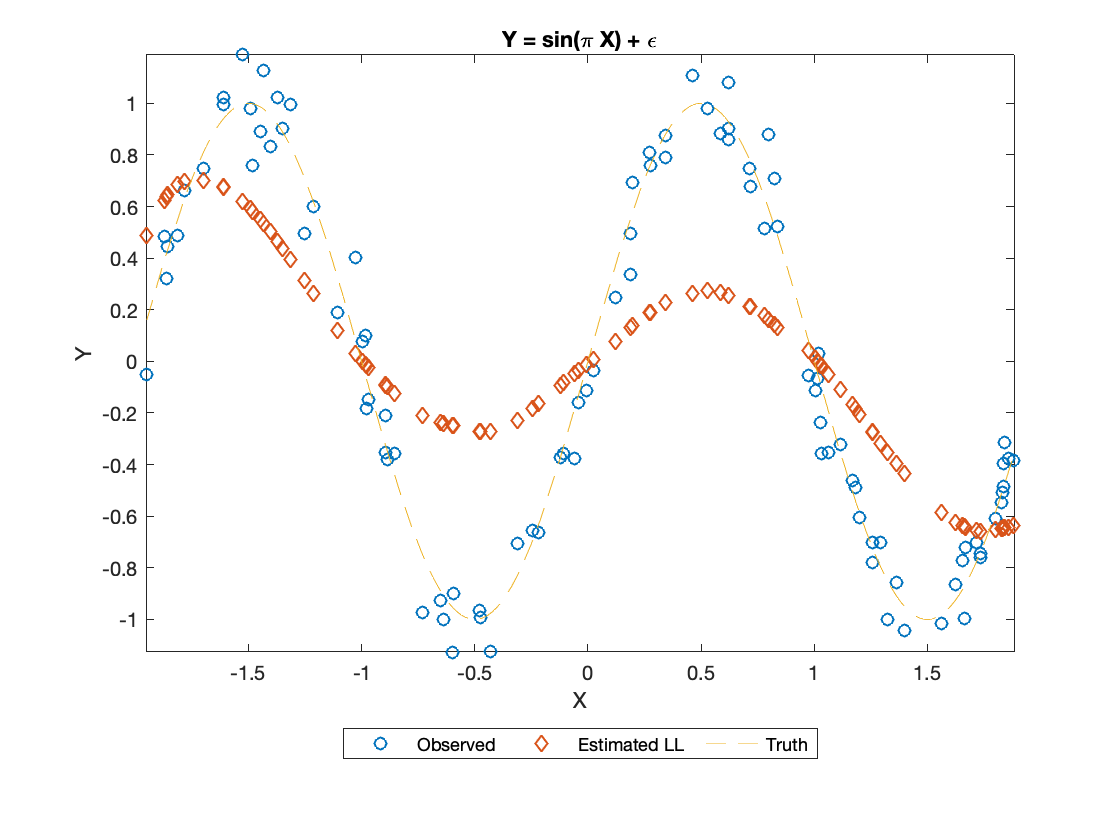

[n, k] = size(X);
L = zeros(n,n);

% diff_ij = (x_j-x_i)
diff = (repmat(X',n,k)-repmat(X,k,n));
%Epanechnikov kernel
kn = 3/4*(ones(n*k)-(diff/h).^2).*(abs(diff./h)<=1);
nOnes = ones(n,1);
for i=1:n
    x = [nOnes diff(i,:)']; 
    w = diag(kn(i,:));
    if det(x'*w*x) ~=0
        proj = x*(x'*w*x)^-1*x'*w;
        L(i,:)=proj(i,:);
    else
        L(i,:)=[zeros(1,i-1) 1 zeros(1,n-i)];
    end
    
end

Y_LL = L*Y;

y_limits = [min(min(Y),min(Y_LL)) max(max(Y),max(Y_LL))];
plot(X,Y,'o',X,Y_LL,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated LL','Truth',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,L,rowNames(5));

## Spline Estimators

n_knots = 4; %internal knots

step = floor(n/n_knots);
offset = floor((n-step*(n_knots-1))/2)+1;
indecies = offset:step:n-1;
knots = X(indecies);

order =4; %cubic splines

### Regression Cubic B-Spline

n_knots+order b-splines

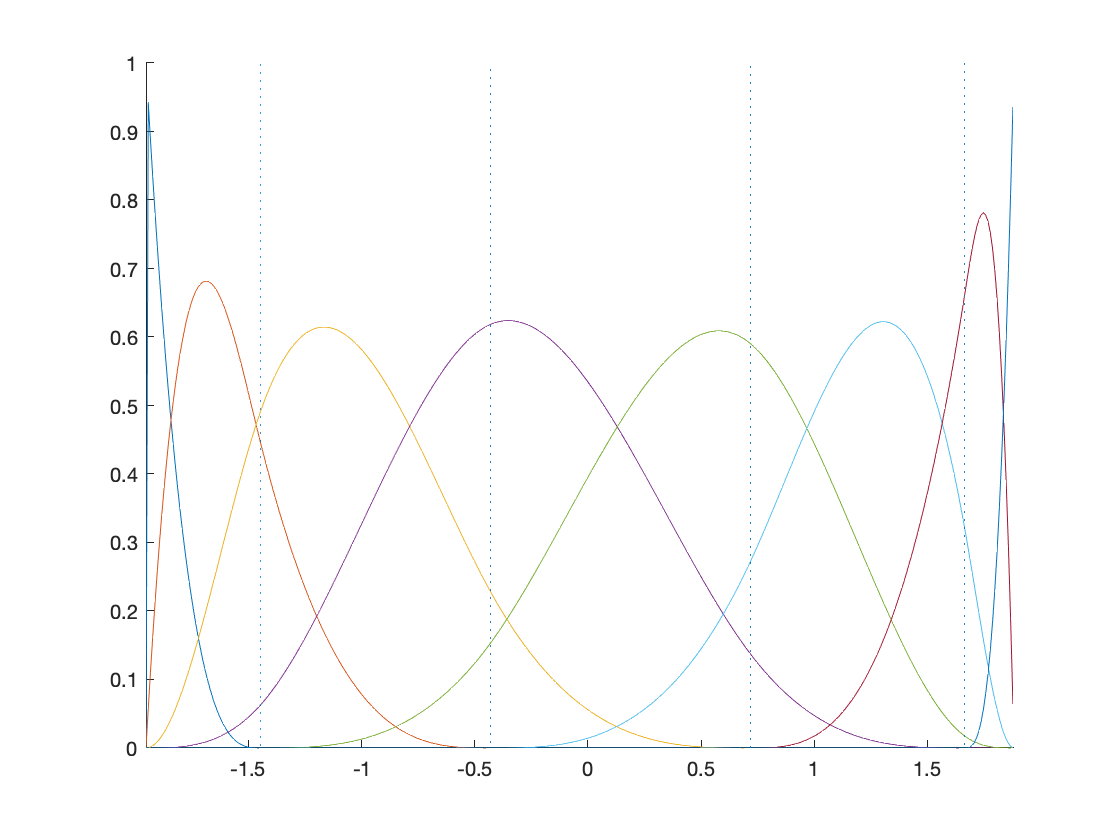

[n k] = size(X);

B = zeros(n,n_knots+order);
basisKnots=[X(1); knots; X(end)];
knotBasis = makeBSplines(basisKnots, order);
bDeriv2 = repmat(mkpp([0 0],0),n_knots+order,1);

figure;
hold on;
for i=1:size(knotBasis,1)
    plotPP(xx, knotBasis(i))
    bDeriv2(i) = fnder(fnder(knotBasis(i)));
    B(:,i) = ppval(knotBasis(i),X).*...
        (X>=knotBasis(i).breaks(1)).*...
        (X<=knotBasis(i).breaks(end));
end
ax = gca;
for i=1:n_knots
    ax.ColorOrderIndex = size(knotBasis,1);
    l = plot([knots(i) knots(i)], [0 1],':'); 
    set(get(get(l,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
end
xlim([X(1) X(end)])
hold off;

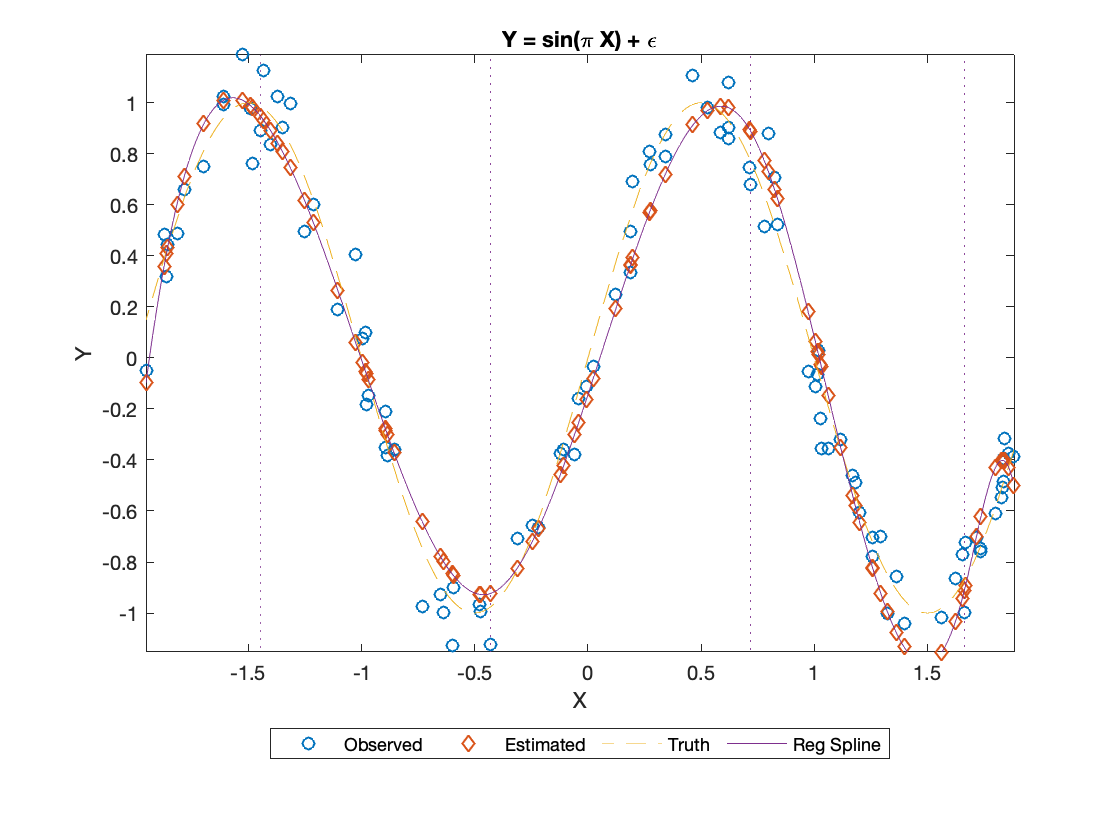


RS = B*(B'*B)^-1*B';
Y_RS = RS*Y;
beta = (B'*B)^-1*B'*Y;

%for plotting the spline curve
xx = X(1):0.01:X(end);
yy = zeros(size(xx));
for l = 1:(n_knots+order)
    yy = yy + beta(l)*ppval(knotBasis(l),xx).*...
        (xx>=knotBasis(l).breaks(1)).*...
        (xx<=knotBasis(l).breaks(end));
end

figure;
y_limits = [min(min(Y),min(Y_RS)) max(max(Y),max(Y_RS))];
plot(X,Y,'o',X,Y_RS,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-')
ax = gca;
for i=1:n_knots
    ax.ColorOrderIndex = 4;
    l = plot([knots(i) knots(i)], y_limits,':'); 
    set(get(get(l,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
end
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated', 'Truth','Reg Spline',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,RS,rowNames(6));

### Smoothing Cubic Spline

lambda = 0.2;

like interpolation spline, but with added omega term


$$||y-G\beta||_2^2 + \lambda\beta^T\Omega\beta \text{, where } G_{ij} = g_j(x_i) \text{ and } \Omega_{jk} = \int g''_j(t)g''_k(t)dt \enspace i,j = 1,...,n$$



$$\hat{\beta} = (G^TG+\lambda\Omega)^{-1}G^Ty$$


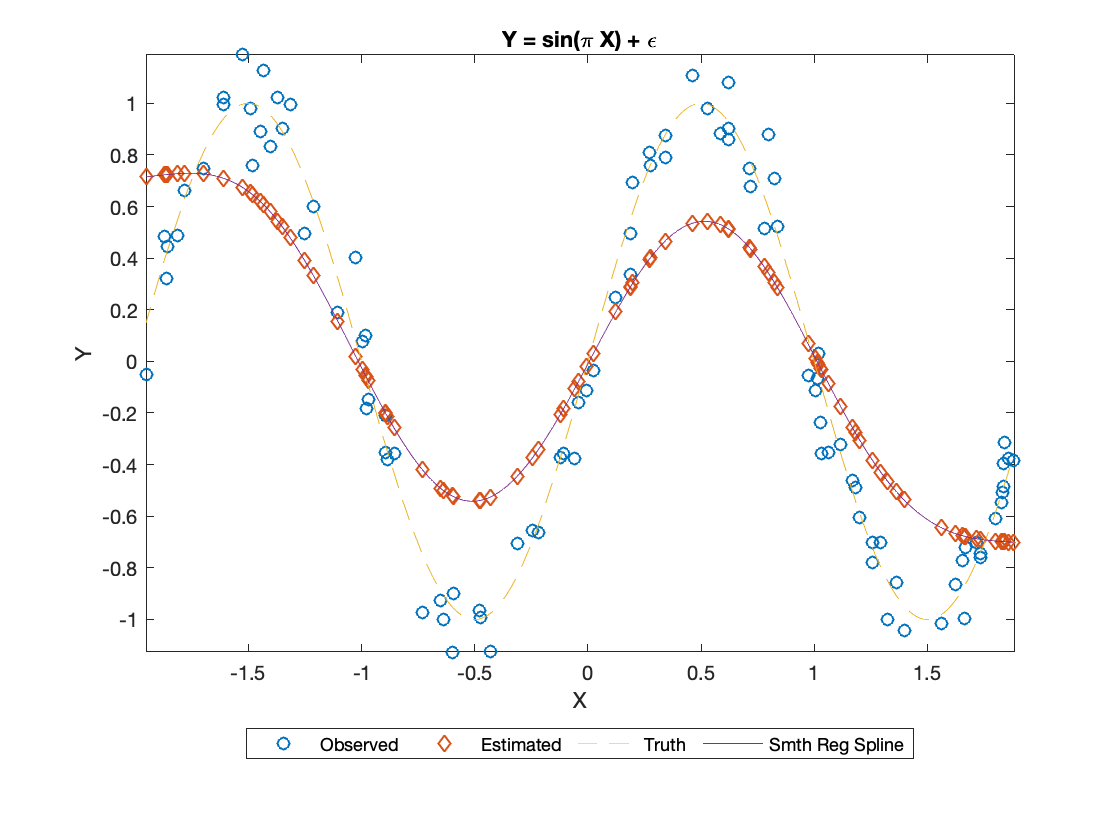

[n k] = size(X);
%not-a-knot conditions
if order>2
    skipStart = 1:2:(order-2);
    skipEnd = fliplr(n:-2:(n-order+2)); 
    basisX = [X(skipStart);X(order-1:n-order+1);...
        X(skipEnd)];
else
    basisX = X;
end
bBasis = makeBSplines(basisX, order);
n_basis = size(bBasis,1);
bDeriv2 = repmat(mkpp([0 0],0),n_basis);
G = zeros(n,n_basis);

for i=1:n_basis
    bDeriv2(i) = fnder(fnder(bBasis(i)));
    G(:,i) = ppval(bBasis(i),X).*...
        (X>=bBasis(i).breaks(1) & ...
        X<=bBasis(i).breaks(end));
end
   
omega = zeros(n_basis,n_basis);
for i = 1:n_basis
    startJ = max(1,i-order+1);
    stopJ = min(n_basis,i+order-1);
    % leveraging the banded nature of omega
    for j = startJ:stopJ
        tempInt = fnint(convPP(bDeriv2(i),...
            bDeriv2(j)));
        omega(i,j) = ppval(tempInt,tempInt.breaks(end)) - ...
            ppval(tempInt,tempInt.breaks(1));
    end
end

inner = (G'*G+lambda*omega)^-1*G';
S = G*inner;
Y_S = S*Y;
beta = inner*Y;

%for plotting the spline curve
xx = X(1):0.01:X(end);
yy = zeros(size(xx));
for l = 1:n_basis
    yy = yy + beta(l)*ppval(bBasis(l),xx).*...
        (xx>=bBasis(l).breaks(1)).*...
        (xx<=bBasis(l).breaks(end));
end

figure;
y_limits = [min(min(Y),min(Y_S)) max(max(Y),max(Y_S))];
plot(X,Y,'o',X,Y_S,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated', 'Truth','Smth Reg Spline',...
    'Location','bestoutside','Orientation','horizontal');
title(plot_title);
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,S,rowNames(7));

## Interpolating Cubic Splines

Using Atkinson, p 168: $M_i=s''(x_i) \enspace \text{ for }i=1,2,...,n \text{ and } h_i = x_{i+1}-x_i$

$s''(x) = \frac{(x_{i+1}-x)M_i +(x-x_i)M_{i+1}}{h_i}, x_i \le x \le x_{i+1} \enspace 1\le i \le n-1$ and therefore


$$s(x) =  \frac{(x_{i+1}-x)^3M_i +(x-x_i)^3M_{i+1}}{6h_i}+\frac{(x_{i+1}-x)y_i+(x-x_i)y_{i+1}}{h_i} -\frac{h_i}{6}\big((x_{i+1}-x)M_i +(x-x_i)M_{i+1}\big)$$



$$\frac{h_{i-1}}{6}M_{i-1} + \frac{h_{i-1}+h_i}{3}M_i + \frac{h_i}{6}M_{i+1} = \frac{y_{i+1}-y_i}{h_i}-\frac{y_i-y_{i-1}}{h_{i-1}} \text{ for } i=2,3,...,n-1$$


### Not-A-Knot


$$s'''(x) \text{ continuous at }x_2,x_{n-1} 
\rightarrow \frac{M_2-M_1}{h_1}= \frac{M_3-M_2}{h_2} \text{ and }
\frac{M_{n-1}-M_{n-2}}{h_{n-2}}=\frac{M_n-M_{n-1}}{h_{n-1}}$$


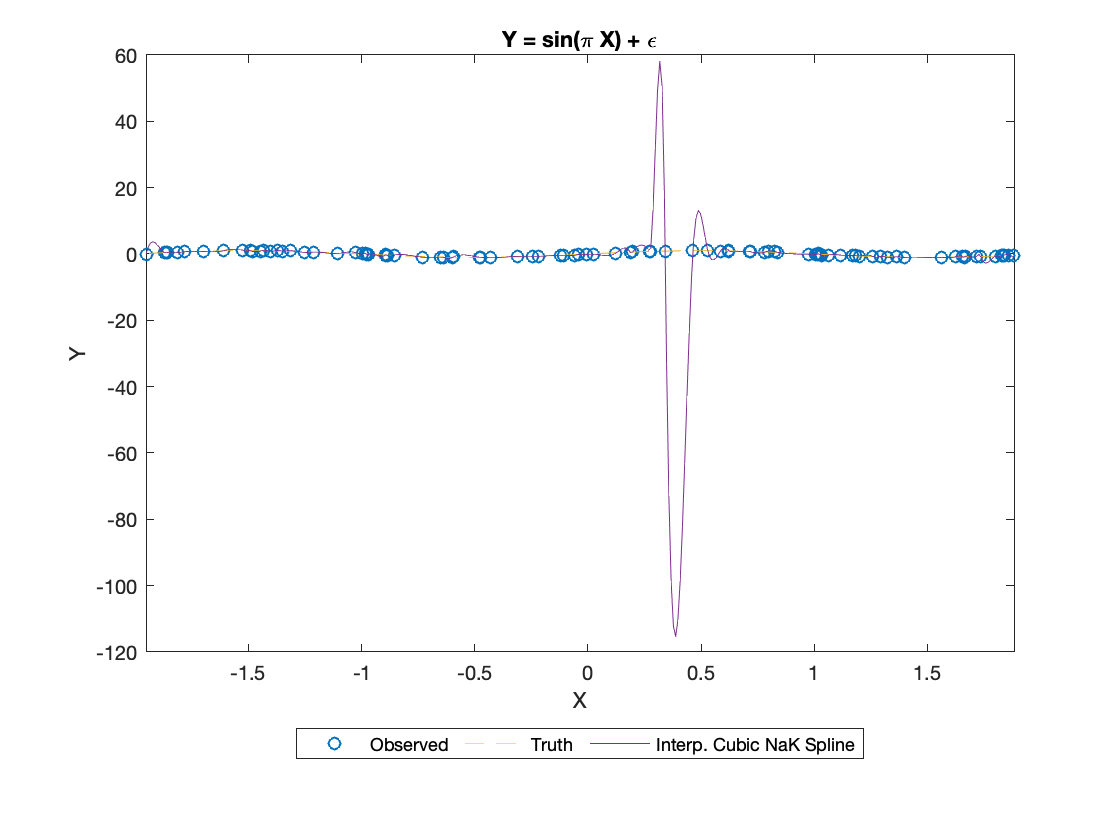

[n k] = size(X);
%not-a-knot conditions
if order>2
    skipStart = 1:2:(order-2);
    skipEnd = fliplr(n:-2:(n-order+2)); 
    basisX = [X(skipStart);X(order-1:n-order+1);...
        X(skipEnd)];
else
    basisX = X;
end
bBasis = makeBSplines(basisX, order);
n_basis = size(bBasis,1);

M = zeros(n,n_basis);
for i=1:n_basis
    M(:,i) = ppval(bBasis(i),X).*...
        (X>=bBasis(i).breaks(1)).*...
        (X<=bBasis(i).breaks(end));
end

beta = M^-1*Y;

xx = X(1):0.01:X(end);
yy = zeros(size(xx));
for l = 1:n_basis
    yy = yy + beta(l)*ppval(bBasis(l),xx).*...
        (xx>=bBasis(l).breaks(1)).*...
        (xx<=bBasis(l).breaks(end));
end

plot(X,Y,'o');
hold on;
ax = gca;
ax.ColorOrderIndex = 3;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
title('Y = sin(\pi X) + \epsilon');
legend('Observed', 'Truth','Interp. Cubic NaK Spline',...
    'Location','bestoutside','Orientation','horizontal');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
%ylim([min(Y) max(Y)])
hold off;

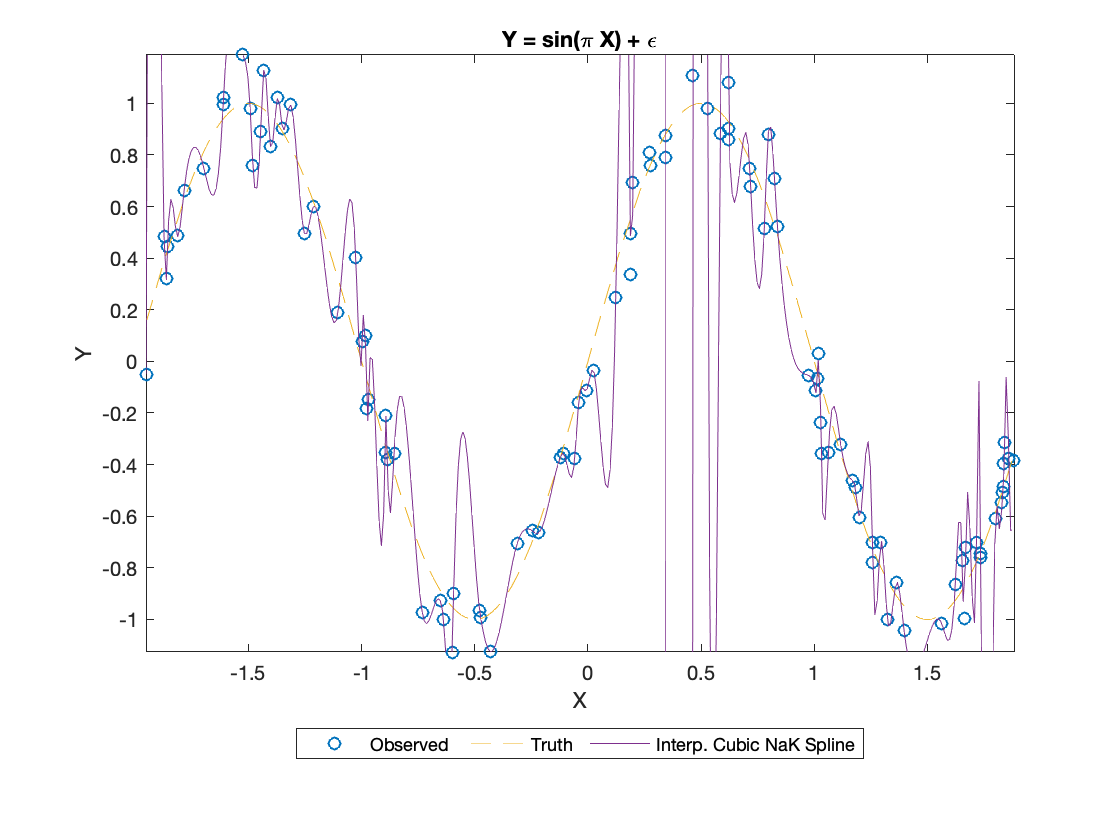


plot(X,Y,'o');
hold on;
ax = gca;
ax.ColorOrderIndex = 3;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
title(plot_title);
legend('Observed', 'Truth','Interp. Cubic NaK Spline',...
    'Location','bestoutside','Orientation','horizontal');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
ylim([min(Y) max(Y)])
hold off;


smoothness = loadSmoothness(smoothness,varNames,eye(n),rowNames(8));

smoothness

smoothness = 8×5 table
                    df_Var    df_Px     df_Fit    sum_SVD    sum_eig
                    ______    ______    ______    _______    _______

    linear               1         1         1         1          1 
    affine               2         2         2         2          2 
    glPoly               8         8         8         8          8 
    NW              2.7781    3.3924    4.0067    3.9398     3.3924 
    LL              3.8254    4.3649    4.9043     4.907     4.3649 
    regSpline            8         8         8         8          8 
    smoothSpline    4.4849    5.5981    6.7114    5.5981     5.5981 
    interpSpline       100       100       100   

## Helper Functions

function tab = loadSmoothness(tab,vars,mat,rowName)
    tab(rowName,vars(1)) = {trace(mat*mat')};
    tab(rowName,vars(2)) = {trace(mat)};
    tab(rowName,vars(3)) = {trace(2*mat -mat*mat')};
    tab(rowName,vars(4)) = {sum(svd(mat))};
    tab(rowName,vars(5)) = {sum(eig(mat))};
end

function basis = makeBSplines(vec, order)
%depends on vec already being sorted
%implementation of Cox-deBoor Recursion algorithm
    vec = [repmat(vec(1),order-1,1); vec; repmat(vec(end),order-1,1)];
    [n k] = size(vec);
    
    diff = zeros(n-1,order);
    for i = 1:order
        diff(1:end-i+1,i) = vec(1+i:end)-vec(1:end-i);
    end
    
    tempBasis = repmat(mkpp([0 0],0),n-1,order);
    for i=1:n-1
        tempBasis(i,1) = mkpp([vec(i) vec(i+1)], 1);
    end

    for l = 1:order-1
        for m=1:n-l-1
        
            if (diff(m,l)==0)
                firstTerm = mkpp([vec(m) vec(m+l)],0);
            else
                firstTerm = convPP(tempBasis(m,l),...
                    mkpp([vec(m) vec(m+l)],[1/diff(m,l) 0]));
            end
            
            if (diff(m+1,l)==0)
                secondTerm = mkpp([vec(m+1) vec(m+l+1)],0);
            else
                secondTerm = convPP(tempBasis(m+1,l),...
                    mkpp([vec(m+1) vec(m+1+l)],[-1/diff(m+1,l) 1]));
            end
            
            tempBasis(m,l+1) = addPP(firstTerm,secondTerm);
        end
    end
    basis = tempBasis(1:end-order+1,order);
end

function plotPP(xx,pp)
    plot(xx,ppval(pp,xx).*(xx>pp.breaks(1)).*(xx<pp.breaks(end)))
end


function pp = convPP(ppA,ppB)
    coefsA = ppA.coefs;
    ordA = size(coefsA,2);
    coefsB = ppB.coefs;
    ordB = size(coefsB,2);
    ord = ordA+ordB-1;

    breaks = unique([ppA.breaks ppB.breaks], 'first');
    coefs = zeros(size(breaks,2)-1,ord);
    
    a=1;b=1;
    for i=1:size(coefs,1)
        k = breaks(i);
        if a<=size(coefsA,1) & k==ppA.breaks(a+1)
            a = a+1;
        end
        if b<=size(coefsB,1) & k==ppB.breaks(b+1)
            b = b+1;
        end

        subCoefA = zeros(1,ordA);
        if ppA.breaks(a) <= k & a<=size(coefsA,1)
            for j=0:ordA-1
                subCoefA(ordA-j:end) = subCoefA(ordA-j:end) + ...
                    coefsA(a,ordA-j)*binomCoef(j).*(k-ppA.breaks(a)).^(0:j);
            end
        end
        
        subCoefB = zeros(1,ordB);
        if ppB.breaks(b) <= k & b<=size(coefsB,1)

            for j=0:ordB-1
                subCoefB(ordB-j:end) = subCoefB(ordB-j:end) + ...
                    coefsB(b,ordB-j)*binomCoef(j).*(k-ppB.breaks(b)).^(0:j);
            end
        end
        
        coefs(i,:) = conv(subCoefA,subCoefB);       
    end
    pp = mkpp(breaks,coefs);
end

function pp = addPP(ppA,ppB)
    coefsA = ppA.coefs;
    ordA = size(coefsA,2);
    coefsB = ppB.coefs;
    ordB = size(coefsB,2);
    ord = max(ordA,ordB);
    if ordA<ord
        coefsA = [zeros(size(ppA.breaks,1),ord-ordA) coefsA];
    elseif ordB<ord
        coefsB = [zeros(size(ppB.breaks,1),ord-ordB) coefsB];    
    end
    
    breaks = unique([ppA.breaks ppB.breaks], 'first');
    if size(breaks,2)==1
        breaks = [breaks breaks];
    end
    coefs = zeros(size(breaks,2)-1,ord);
    a=1;b=1;
    kA = ppA.breaks(a);
    kB = ppB.breaks(b);
    for i=1:size(coefs,1)
        k = breaks(i);
        if a<=size(coefsA,1) & k==ppA.breaks(a+1)
            a = a+1;
            kA = ppA.breaks(a);
        end
        if b<=size(coefsB,1) & k==ppB.breaks(b+1)
            b = b+1;
            kB = ppB.breaks(b);
        end
        
        if kA <= k & a<=size(coefsA,1)
            dA = k-kA;
            for j=0:ord-1
                coefs(i,ord-j:end) = coefs(i,ord-j:end) + ...
                    coefsA(a,ord-j)*binomCoef(j).*dA.^(0:j);
            end
        end
        
        if kB <= k & b<=size(coefsB,1)
            dB = k-kB;
            for j=0:ord-1
                coefs(i,ord-j:end) = coefs(i,ord-j:end) + ...
                    coefsB(b,ord-j)*binomCoef(j).*dB.^(0:j);
            end
        end
    end
    pp = mkpp(breaks,coefs);
end

function b = binomCoef(n)
    b = factorial(n)./(factorial(0:n).*factorial(n:-1:0));
end


average predictive squared error


$$PSE(\lambda) = \frac{1}{n} \sum\limits_{i=1}^n E\{Y_i^* - \hat{f}_\lambda(x_i)\}^2 =  \frac{1}{n} \sum\limits_{i=1}^n E\{f(x_i)+\epsilon_i^* - \hat{f}_\lambda(x_i)\}^2 $$


## Specification help

Nadaraya-Watson: [https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf](https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf) and [http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf](http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf) (cause I can't put my hands on the notes from Fall 2017)

Local linear: [http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf,](http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf,) [https://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20local%20Linear%20Estimator.pdf](https://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20local%20Linear%20Estimator.pdf)

Splines: [http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf,](http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf,)  [http://www.stat.columbia.edu/~madigan/DM08/regularization.ppt.pdf,](http://www.stat.columbia.edu/~madigan/DM08/regularization.ppt.pdf,) [https://cran.r-project.org/web/packages/crs/vignettes/spline_primer.pdf,](https://cran.r-project.org/web/packages/crs/vignettes/spline_primer.pdf,) and [http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf](http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf)